# **CAMINATAS**

## **Criterios de estabilidad**

- **Metodo de proyeccion del centro de gravedad: **El vehiculos es estaticamente estable si la proyeccion horizontal de su centro de gravedad (COG) se encuentra dentro del poligono de soporte

- **Margen de estabilidad estatico (**$S_{\textrm{SM}}$**): **Es definido como la distancia mas pequeña de la proyeccion del COG a cualquiera de los bordes del poligono de soporte (dificil de calcular).

- **Margen de estabilidad longitudinal (**$S_{\textrm{LSM}}$**): **Es definido como la distancia mas pequeña de la proyeccion  del COG entrelos bordes delanteros o trasero del poligono de soporte a lo largo del eje longitudinal de la maquina

- **Margen de estabilidad longitudinal de cangrejo (**$S_{\textrm{CLSM}}$**): **Es la distancia mas pequeña de la proyeccion del COG entre los bordes grontal y trasero del poligono de soporte, a lo largo del eje de movimiento de la maquina

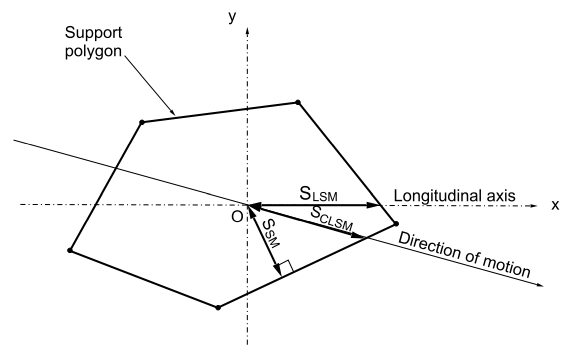

## **Caminatas Periodicas**

El cuerpo está en constante movimiento, mientras que todas las piernas se mueven simultáneamente.

Las marchas onduladas son un tipo especial de marcha utilizada por mamiferos e insectos a baja velocidad

**Gait (Caminata/ Marcha): **Se define como el tiempo y la ubicacion de la colocacion y elevacion de cada pata, coordinando con el mivmiento del cuerpo en sus seis grados de libertad, con el fin de mover el cuerpo de un lugar a otro.

Por convencion, las patas de la izquierda se enumeran con numeros impares, y las patas de la derecha con numeros pares.

**Evento: ** Un evento es definido como la colocacion o elevacion  de una pierna robotica. 

- Para un robot de $n$ piernas, la colocacion o apoyo $i$ es denotada como el evento $i$.

- Para una elevacion de pierna $i$, se denota el evento $i+n$

- Creando $2n$ eventos diferentes

Asi, una caminata expresada como una secuencia de eventos puede ser: 2-4-5-7-3-1-8-6

- **singular gait: **Pueden ocurrir dos eventos al mismo tiempo

- **no singular gait: **Marchas totalmente ordenadas

El numero posible de combinaciones posibles para una caminata no singular de un robot cuadrupedo esta definido por la permutacion de  $2n$. Teniendo en cuenta el número de secuencias de eventos a partir de una dada, el resultado es $N\;=\left(2n-1\right)!=5040$. Pero si ahora se considera la estabilidad estatica, en la cual almenos 3 patas deben estar soportando el cuerpo y una en el aire, se reduce drasticamente las cobinaciones posibles a $N=\left(n-1\right)!=6$

## Definiciones requeridas para la formulacion de una caminata

- **Factor de servicio (**$\beta {\;}_i$): Es la fraccion del ciclo durante que la pierna permanece en el suelo. Si es igual para todas las piernas, la caminata es regular

- **Fase de la pierna (**$\phi {\;}_i$): es el tiempo normalizado en el que la colocación de la pierna i en el suelo va a la altura de la colocación de la pierna 1. ( La pierna 1 es normalmente la pierna de referencia).

- **La carrera de la pierna (**$R$): Es la distancia que se mueve un pie en relación con el cuerpo durante la fase de apoyo. R debe estar dentro del espacio de trabajo de la rama definido por Rx y Ry

- **El paso del trazo  (P):** es la distancia entre los centros del trazo de las piernas adyacentes. Px es la distancia entre los centros de trazo de los tramos colaterales y Py es la distancia entre los centros de trazo de los tramos contralaterales

- **La longitud de la zancada (**$\lambda$**):** de una marcha es la distancia recorrida por el centro de gravedad COG del cuerpo a lo largo de un ciclo de locomoción. Si la marcha es periódica, entonces


$$\lambda =\frac{R}{\beta }$$


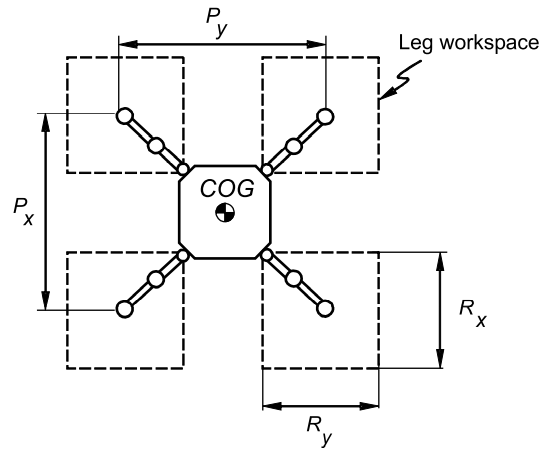

## **Caminatas Continuas**

Cuando el cuerpo esta en constante movimiento, mientras que todas las piernas se mueven simultaneamente.

## Caminatas Discontinuas

Esta marcha se da porque el cuerpo se impulsa hacia adelante o hacia atras con todos los pies colocados de forma segura en el suelo, y una pierna se transfiere con las otras tres piernas y el cuerpo totalmente detenidos, esto genera un movimiento corporal intermitente. Este tipo de marcha son mas beneficiosas para las maquinas con patas, ya que son mas faciles de implementar y ofrecen un mejor margen de estabilidad longitudinal que las caminatas continuas.

Para generar una caminata discontinua periodica, se deben tener en cuenta los siguientes aspectos:

- Si una pierna en su fase de apoyo alcanza el límite trasero de su espacio de trabajo (límite cinemático), esta pierna debe cambiar a la fase de transferencia para colocarse en su límite cinemático delantero.

- El cuerpo se impulsa hacia adelante con todas las piernas en el suelo. Después de un movimiento corporal, al menos una pierna debe permanecer en su límite cinemático trasero para realizar una fase de transferencia al siguiente movimiento de la pierna.

- La pierna que es contralateral y no adyacente (CNA) a la pierna de transferencia actual debe colocarse en un punto tal que después de la colocación de la pierna transferida, el COG permanezca en el otro lado de la línea que conecta la pierna CNA con la transferencia. pierna (ver Fig. 3.4). De esta forma, será posible levantar otra pierna manteniendo la estabilidad de la máquina.

- La secuencia de piernas debe ser periódica; esto permitirá unir varios ciclos de locomoción para seguir un camino.

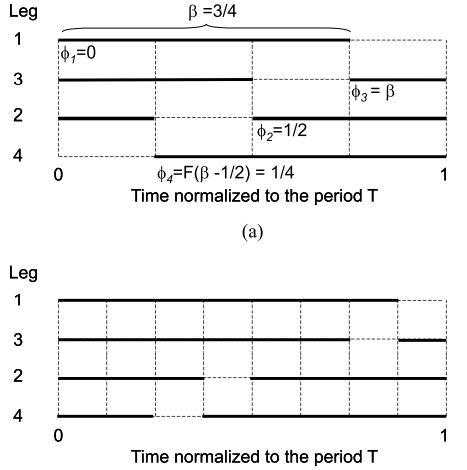

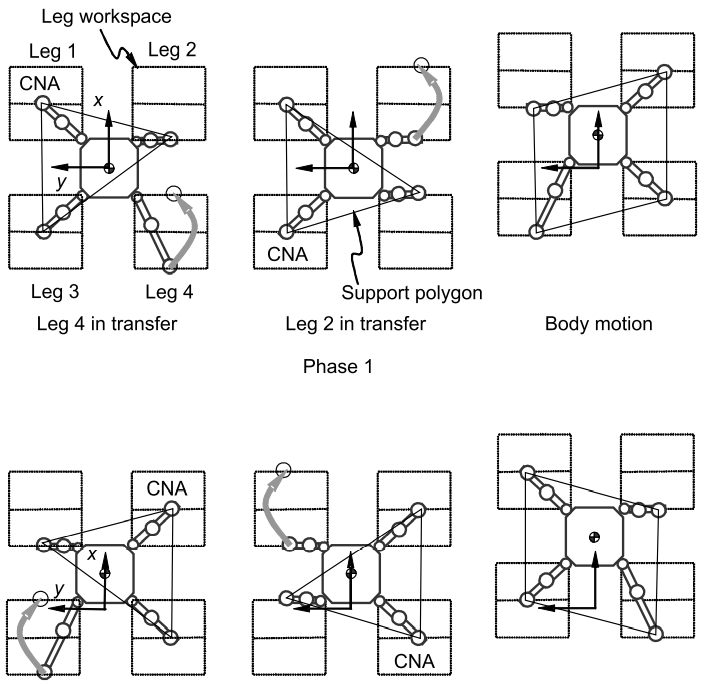

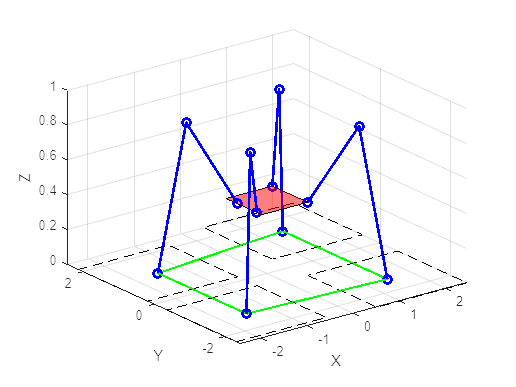

clear all
clc
clf


%Parametros pierna robotica
%Longitud eslabones 
L1 = 0;       
L2 = 1;       
L3 = 1;  
L = L1+L2+L3;

% Dimensiones del cuerpo
a1 = 1;          % Arista 1, distancia en X
a2 = 1;          % Arista 2, distancia en Y
lim_h_i = L/10;   % Liminte inferior de altura
lim_h_u = 4*L/10; %Limite superior de altura
h = 0.42;


%h = [linspace(1,0.2,50),linspace(0.2,1,25)];          % Altura del cuerpo
%rot = [linspace(0,30,50),linspace(30,0,25)];

% Ubicacion de cada pata
% Patas del lado izquierdo numero impar
% Patas del lado derecho numero par
lim_a1_sup = a1/2;
lim_a1_inf = -a1/2;
lim_a2_sup = a2/2;
lim_a2_inf = -a2/2;

ol1 = -0.3682062;
ol3 = 0.18;
ol2 = -0.5;
ol4 = 0.5;

%Definiciones cinematicas
Rx = sqrt(L^2-h^2);
Ry = Rx;



%Vectorees para ubicar cada pierna en su posicion inicia
%compuesto por 6 datos, Ubicacion de la  base, y ubicacion del extremo.
%       [x0,       y0, z0,      x,          y,    z]
leg1 = [lim_a1_inf,ol1,h,-Rx/2+lim_a1_inf,-Ry/2+ol1,0];
leg3 = [lim_a1_inf,ol3,h,-Rx/2+lim_a1_inf,Ry/2+ol3,0];
leg2 = [lim_a1_sup,ol2,h,Rx/2+lim_a1_sup,-Ry/2+ol2,0];
leg4 = [lim_a1_sup,ol4,h,Rx/2+lim_a1_sup,Ry/2+ol4,0];

%Vectores en cada eje coordenado para graficar poligono del cuerpo
X_body = [lim_a1_sup,lim_a1_sup,lim_a1_inf,lim_a1_inf,lim_a1_sup];
Y_body = [lim_a2_inf,lim_a2_sup,lim_a2_sup,lim_a2_inf,lim_a2_inf];
Z_body = [h,h,h,h,h];

%Cinematica inversa para obtener las rotaciones de las articulaciones en la
%posicion inicial
[q1_l1,q2_l1,q3_l1] = IK(leg1(3),leg1(1),leg1(2),L1,L2,L3,leg1(4),leg1(5),leg1(6));
[q1_l2,q2_l2,q3_l2] = IK(leg2(3),leg2(1),leg2(2),L1,L2,L3,leg2(4),leg2(5),leg2(6));
[q1_l3,q2_l3,q3_l3] = IK(leg3(3),leg3(1),leg3(2),L1,L2,L3,leg3(4),leg3(5),leg3(6));
[q1_l4,q2_l4,q3_l4] = IK(leg4(3),leg4(1),leg4(2),L1,L2,L3,leg4(4),leg4(5),leg4(6));

% Se utiliza cinematica directa para poder graficar las piernas. Se
% obitienen las coordendas para cada articulacion
[p1,pos1] = FK_1(L1,L2,L3,q1_l1,q2_l1,q3_l1,leg1(1:3),0);
[p2,pos2] = FK_1(L1,L2,L3,q1_l2,q2_l2,q3_l2,leg2(1:3),0);
[p3,pos3] = FK_1(L1,L2,L3,q1_l3,q2_l3,q3_l3,leg3(1:3),0);
[p4,pos4] = FK_1(L1,L2,L3,q1_l4,q2_l4,q3_l4,leg4(1:3),0);


%Vectores para graficar espacios de trabajo de cada pierna
ws_l1 = [lim_a1_inf,lim_a1_inf,lim_a1_inf-Rx,lim_a1_inf-Rx,lim_a1_inf;
         ol1,ol1-Ry,ol1-Ry,ol1,ol1;
         0,0,0,0,0];
ws_l2 = [lim_a1_sup,lim_a1_sup,lim_a1_sup+Rx,lim_a1_sup+Rx,lim_a1_sup;
         ol2,ol2-Ry,ol2-Ry,ol2,ol2;
         0,0,0,0,0];
ws_l3 = [lim_a1_inf,lim_a1_inf,lim_a1_inf-Rx,lim_a1_inf-Rx,lim_a1_inf;
         ol3,ol3+Ry,ol3+Ry,ol3,ol3;
         0,0,0,0,0];
ws_l4 = [lim_a1_sup,lim_a1_sup,lim_a1_sup+Rx,lim_a1_sup+Rx,lim_a1_sup;
         ol4,ol4+Ry,ol4+Ry,ol4,ol4;
         0,0,0,0,0];


%Graficar poligono de soporte
poligono = [pos1(1,4),pos3(1,4),pos4(1,4),pos2(1,4),pos1(1,4);
            pos1(2,4),pos3(2,4),pos4(2,4),pos2(2,4),pos1(2,4);
            0,0,0,0,0];

%Graficar Cuerpo en posicion inicial
plot3(X_body,Y_body,Z_body)
patch(X_body,Y_body,Z_body,'red','FaceAlpha',.5)
grid on
hold on
xlabel('X')
ylabel('Y')
zlabel('Z')

%Graficar piernas
plot3(pos1(1,:),pos1(2,:),pos1(3,:),'b-o','LineWidth',2) %Graficar posicion del robot
plot3(pos2(1,:),pos2(2,:),pos2(3,:),'b-o','LineWidth',2) %Graficar posicion del robot
plot3(pos3(1,:),pos3(2,:),pos3(3,:),'b-o','LineWidth',2) %Graficar posicion del robot
plot3(pos4(1,:),pos4(2,:),pos4(3,:),'b-o','LineWidth',2) %Graficar posicion del robot

% Graficar espacio de trabajo
plot3(ws_l1(1,:),ws_l1(2,:),ws_l1(3,:),'k--','LineWidth',0.5)
plot3(ws_l2(1,:),ws_l2(2,:),ws_l2(3,:),'k--','LineWidth',0.5)
plot3(ws_l3(1,:),ws_l3(2,:),ws_l3(3,:),'k--','LineWidth',0.5)
plot3(ws_l4(1,:),ws_l4(2,:),ws_l4(3,:),'k--','LineWidth',0.5)

plot3(poligono(1,:),poligono(2,:),poligono(3,:),'g','LineWidth',1.5)

## Calculos para simular caminata periodica discontinua


%% Puntos de la trayectoria de movimiento
p_f_l1 = [lim_a1_inf-Rx/2,ol1,0];
p_i_l1 = [(p_f_l1(1)-pos1(1,4))/2,(p_f_l1(2)-pos1(2,4))/2,h/3];
via_leg1 = [p_i_l1;p_f_l1];
%Obtener trayectoria con mstraj
%             path vel-eje time origen  paso t_acel
traj = mstraj(via_leg1, [1 1 1], [], [pos1(4),pos1(2,4),pos1(3,4)], 0.1, 2);
% leg1 = [lim_a1_inf,ol1,h,traj(i,1),traj(i,2),traj(i,3)];
for i=1:length(traj)
    leg1(4) = traj(i,1);
    leg1(5) = traj(i,2);
    leg1(6) = traj(i,3);
    [q1_l1(i),q2_l1(i),q3_l1(i)] = IK(leg1(3),leg1(1),leg1(2),L1,L2,L3,leg1(4),leg1(5),leg1(6));
    [p1,pos1(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l1(i),q2_l1(i),q3_l1(i),leg1(1:3),0);
end


% 
% % =========================================================================
% % ========================= LEG 1 =========================================
% % =========================================================================
% 
% 
% 
% p_f_l1 = [lim_a1_inf-Rx/2,ol1,0];
% p_i_l1 = [(p_f_l1(1)+pos1(1,4))/2,(p_f_l1(2)+pos1(2,4))/2,h/4];
% via_leg1 = [p_i_l1;p_f_l1];
% %Obtener trayectoria con mstraj
% %             path vel-eje time origen  paso t_acel
% traj = mstraj(via_leg1, [1 1 1], [], [pos1(1,4),pos1(2,4),pos1(3,4)], 0.35, 2);
% % leg1 = [lim_a1_inf,ol1,h,traj(i,1),traj(i,2),traj(i,3)];
% 
% 
% 
% for i = 1:length(traj)
%     clf
% 
%     leg1(4) = traj(i,1);
%     leg1(5) = traj(i,2);
%     leg1(6) = traj(i,3);
%     [q1_l1(i),q2_l1(i),q3_l1(i)] = IK(leg1(3),leg1(1),leg1(2),L1,L2,L3,leg1(4),leg1(5),leg1(6));
%     [q1_l2(i),q2_l2(i),q3_l2(i)] = IK(leg2(3),leg2(1),leg2(2),L1,L2,L3,leg2(4),leg2(5),leg2(6));
%     [q1_l3(i),q2_l3(i),q3_l3(i)] = IK(leg3(3),leg3(1),leg3(2),L1,L2,L3,leg3(4),leg3(5),leg3(6));
%     [q1_l4(i),q2_l4(i),q3_l4(i)] = IK(leg4(3),leg4(1),leg4(2),L1,L2,L3,leg4(4),leg4(5),leg4(6));
% 
% 
%     [p1,pos1(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l1(i),q2_l1(i),q3_l1(i),leg1(1:3),0);
%     [p2,pos2(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l2(i),q2_l2(i),q3_l2(i),leg2(1:3),0);
%     [p3,pos3(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l3(i),q2_l3(i),q3_l3(i),leg3(1:3),0);
%     [p4,pos4(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l4(i),q2_l4(i),q3_l4(i),leg4(1:3),0);
%     %Graficar Cuerpo en posicion inicial
%     plot3(X_body,Y_body,Z_body)
%     patch(X_body,Y_body,Z_body,'red','FaceAlpha',.5)
%     grid on
%     hold on
%     xlabel('X')
%     ylabel('Y')
%     zlabel('Z')
%     
%     %Graficar piernas
%     plot3(pos1(1,(i-1)*4+1:(i-1)*4+4),pos1(2,(i-1)*4+1:(i-1)*4+4),pos1(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos2(1,(i-1)*4+1:(i-1)*4+4),pos2(2,(i-1)*4+1:(i-1)*4+4),pos2(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos3(1,(i-1)*4+1:(i-1)*4+4),pos3(2,(i-1)*4+1:(i-1)*4+4),pos3(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos4(1,(i-1)*4+1:(i-1)*4+4),pos4(2,(i-1)*4+1:(i-1)*4+4),pos4(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     
%     % Graficar espacio de trabajo
%     plot3(ws_l1(1,:),ws_l1(2,:),ws_l1(3,:),'k--','LineWidth',0.5) 
%     plot3(ws_l2(1,:),ws_l2(2,:),ws_l2(3,:),'k--','LineWidth',0.5)
%     plot3(ws_l3(1,:),ws_l3(2,:),ws_l3(3,:),'k--','LineWidth',0.5)
%     plot3(ws_l4(1,:),ws_l4(2,:),ws_l4(3,:),'k--','LineWidth',0.5)
%     if pos1(3,(i-1)*4+4) > 0
%         poligono = [pos3(1,(i-1)*4+4),pos4(1,(i-1)*4+4),pos2(1,(i-1)*4+4),pos3(1,(i-1)*4+4);
%                     pos3(2,(i-1)*4+4),pos4(2,(i-1)*4+4),pos2(2,(i-1)*4+4),pos3(2,(i-1)*4+4);
%                     pos3(3,(i-1)*4+4),pos4(3,(i-1)*4+4),pos2(3,(i-1)*4+4),pos3(3,(i-1)*4+4)];
%         
%     else
%         poligono = [pos1(1,(i-1)*4+4),pos3(1,(i-1)*4+4),pos4(1,(i-1)*4+4),pos2(1,(i-1)*4+4),pos1(1,(i-1)*4+4);
%                     pos1(2,(i-1)*4+4),pos3(2,(i-1)*4+4),pos4(2,(i-1)*4+4),pos2(2,(i-1)*4+4),pos1(2,(i-1)*4+4);
%                     pos1(3,(i-1)*4+4),pos3(3,(i-1)*4+4),pos4(3,(i-1)*4+4),pos2(3,(i-1)*4+4),pos1(3,(i-1)*4+4)];
%     end
%     
%     plot3(poligono(1,:),poligono(2,:),poligono(3,:),'g','LineWidth',1.5)
%     movieVector(i) = getframe; %Animacion
% end
% 
% % =========================================================================
% % ========================= LEG 3 =========================================
% % =========================================================================
% 
% p_f_l3 = [lim_a1_inf-Rx/2,ol3+Ry,0];
% p_i_l3 = [(p_f_l3(1)+pos3(1,4))/2,(p_f_l3(2)+pos3(2,4))/2,h/4];
% via_leg3 = [p_i_l3;p_f_l3];
% %Obtener trayectoria con mstraj
% %             path vel-eje time origen  paso t_acel
% traj = mstraj(via_leg3, [1 1 1], [], [pos3(1,4),pos3(2,4),pos3(3,4)], 0.35, 2);
% % leg1 = [lim_a1_inf,ol1,h,traj(i,1),traj(i,2),traj(i,3)];
% for i = 1:length(traj)
%     clf
% 
%     leg3(4) = traj(i,1);
%     leg3(5) = traj(i,2);
%     leg3(6) = traj(i,3);
%     [q1_l1(i),q2_l1(i),q3_l1(i)] = IK(leg1(3),leg1(1),leg1(2),L1,L2,L3,leg1(4),leg1(5),leg1(6));
%     [q1_l2(i),q2_l2(i),q3_l2(i)] = IK(leg2(3),leg2(1),leg2(2),L1,L2,L3,leg2(4),leg2(5),leg2(6));
%     [q1_l3(i),q2_l3(i),q3_l3(i)] = IK(leg3(3),leg3(1),leg3(2),L1,L2,L3,leg3(4),leg3(5),leg3(6));
%     [q1_l4(i),q2_l4(i),q3_l4(i)] = IK(leg4(3),leg4(1),leg4(2),L1,L2,L3,leg4(4),leg4(5),leg4(6));
% 
% 
%     [p1,pos1(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l1(i),q2_l1(i),q3_l1(i),leg1(1:3),0);
%     [p2,pos2(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l2(i),q2_l2(i),q3_l2(i),leg2(1:3),0);
%     [p3,pos3(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l3(i),q2_l3(i),q3_l3(i),leg3(1:3),0);
%     [p4,pos4(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l4(i),q2_l4(i),q3_l4(i),leg4(1:3),0);
%     %Graficar Cuerpo en posicion inicial
%     plot3(X_body,Y_body,Z_body)
%     patch(X_body,Y_body,Z_body,'red','FaceAlpha',.5)
%     grid on
%     hold on
%     xlabel('X')
%     ylabel('Y')
%     zlabel('Z')
%     
%     %Graficar piernas
%     plot3(pos1(1,(i-1)*4+1:(i-1)*4+4),pos1(2,(i-1)*4+1:(i-1)*4+4),pos1(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos2(1,(i-1)*4+1:(i-1)*4+4),pos2(2,(i-1)*4+1:(i-1)*4+4),pos2(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos3(1,(i-1)*4+1:(i-1)*4+4),pos3(2,(i-1)*4+1:(i-1)*4+4),pos3(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos4(1,(i-1)*4+1:(i-1)*4+4),pos4(2,(i-1)*4+1:(i-1)*4+4),pos4(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     
%     % Graficar espacio de trabajo
%     plot3(ws_l1(1,:),ws_l1(2,:),ws_l1(3,:),'k--','LineWidth',0.5) 
%     plot3(ws_l2(1,:),ws_l2(2,:),ws_l2(3,:),'k--','LineWidth',0.5)
%     plot3(ws_l3(1,:),ws_l3(2,:),ws_l3(3,:),'k--','LineWidth',0.5)
%     plot3(ws_l4(1,:),ws_l4(2,:),ws_l4(3,:),'k--','LineWidth',0.5)
% 
%     if pos3(3,(i-1)*4+4) > 0.001
%         poligono = [pos1(1,(i-1)*4+4),pos4(1,(i-1)*4+4),pos2(1,(i-1)*4+4),pos1(1,(i-1)*4+4);
%                     pos1(2,(i-1)*4+4),pos4(2,(i-1)*4+4),pos2(2,(i-1)*4+4),pos1(2,(i-1)*4+4);
%                     pos1(3,(i-1)*4+4),pos4(3,(i-1)*4+4),pos2(3,(i-1)*4+4),pos1(3,(i-1)*4+4)];
%         
%     else
%         poligono = [pos1(1,(i-1)*4+4),pos3(1,(i-1)*4+4),pos4(1,(i-1)*4+4),pos2(1,(i-1)*4+4),pos1(1,(i-1)*4+4);
%                     pos1(2,(i-1)*4+4),pos3(2,(i-1)*4+4),pos4(2,(i-1)*4+4),pos2(2,(i-1)*4+4),pos1(2,(i-1)*4+4);
%                     pos1(3,(i-1)*4+4),pos3(3,(i-1)*4+4),pos4(3,(i-1)*4+4),pos2(3,(i-1)*4+4),pos1(3,(i-1)*4+4)];
%     end
% 
%     
%     
%     plot3(poligono(1,:),poligono(2,:),poligono(3,:),'g','LineWidth',1.5)
%     movieVector(i) = getframe; %Animacion
% end
% 
% % =========================================================================
% % ========================= BODY =========================================
% % =========================================================================
% 
% p_f_l3 = [O_body(1),O_body(2)+Ry,h];
% p_i_l3 = [(p_f_l3(1)+O_body(1))/2,(p_f_l3(2)+O_body(2))/2,h];
% via_body = [p_i_l3;p_f_l3];
% %Obtener trayectoria con mstraj
% %             path vel-eje time origen  paso t_acel
% traj = mstraj(via_body, [1 1 1], [], [pos3(1,4),pos3(2,4),pos3(3,4)], 0.35, 2);
% % leg1 = [lim_a1_inf,ol1,h,traj(i,1),traj(i,2),traj(i,3)];
% for i = 1:length(traj)
%     clf
% 
%     leg3(4) = traj(i,1);
%     leg3(5) = traj(i,2);
%     leg3(6) = traj(i,3);
%     [q1_l1(i),q2_l1(i),q3_l1(i)] = IK(leg1(3),leg1(1),leg1(2),L1,L2,L3,leg1(4),leg1(5),leg1(6));
%     [q1_l2(i),q2_l2(i),q3_l2(i)] = IK(leg2(3),leg2(1),leg2(2),L1,L2,L3,leg2(4),leg2(5),leg2(6));
%     [q1_l3(i),q2_l3(i),q3_l3(i)] = IK(leg3(3),leg3(1),leg3(2),L1,L2,L3,leg3(4),leg3(5),leg3(6));
%     [q1_l4(i),q2_l4(i),q3_l4(i)] = IK(leg4(3),leg4(1),leg4(2),L1,L2,L3,leg4(4),leg4(5),leg4(6));
% 
% 
%     [p1,pos1(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l1(i),q2_l1(i),q3_l1(i),leg1(1:3),0);
%     [p2,pos2(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l2(i),q2_l2(i),q3_l2(i),leg2(1:3),0);
%     [p3,pos3(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l3(i),q2_l3(i),q3_l3(i),leg3(1:3),0);
%     [p4,pos4(:,(i-1)*4+1:(i-1)*4+4)] = FK_1(L1,L2,L3,q1_l4(i),q2_l4(i),q3_l4(i),leg4(1:3),0);
%     %Graficar Cuerpo en posicion inicial
%     plot3(X_body,Y_body,Z_body)
%     patch(X_body,Y_body,Z_body,'red','FaceAlpha',.5)
%     grid on
%     hold on
%     xlabel('X')
%     ylabel('Y')
%     zlabel('Z')
%     
%     %Graficar piernas
%     plot3(pos1(1,(i-1)*4+1:(i-1)*4+4),pos1(2,(i-1)*4+1:(i-1)*4+4),pos1(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos2(1,(i-1)*4+1:(i-1)*4+4),pos2(2,(i-1)*4+1:(i-1)*4+4),pos2(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos3(1,(i-1)*4+1:(i-1)*4+4),pos3(2,(i-1)*4+1:(i-1)*4+4),pos3(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     plot3(pos4(1,(i-1)*4+1:(i-1)*4+4),pos4(2,(i-1)*4+1:(i-1)*4+4),pos4(3,(i-1)*4+1:(i-1)*4+4),'b-o','LineWidth',2) %Graficar posicion del robot
%     
%     % Graficar espacio de trabajo
%     plot3(ws_l1(1,:),ws_l1(2,:),ws_l1(3,:),'k--','LineWidth',0.5) 
%     plot3(ws_l2(1,:),ws_l2(2,:),ws_l2(3,:),'k--','LineWidth',0.5)
%     plot3(ws_l3(1,:),ws_l3(2,:),ws_l3(3,:),'k--','LineWidth',0.5)
%     plot3(ws_l4(1,:),ws_l4(2,:),ws_l4(3,:),'k--','LineWidth',0.5)
%     
%     plot3(poligono(1,:),poligono(2,:),poligono(3,:),'g','LineWidth',1.5)
%     movieVector(i) = getframe; %Animacion
% end